Esercitazione 1 - ECG

Obiettivo 1: implementare una funzione per identificare i picchi R all'interno di ciascun segnale.

load("data.mat")

Caricamento del dato nel workspace utilizzando la funzione `load().`

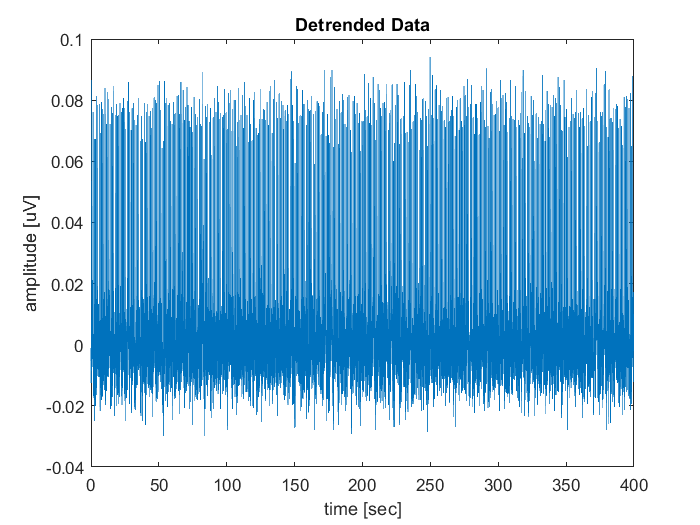

k = 0.05; % [s]
data1 = reshape(data1,fs*k,[]);
dataNoTrend = detrend(data1);
dataNoTrend = dataNoTrend(:);
figure, plot(time,dataNoTrend)
title('Detrended Data')
ylabel('amplitude [uV]')
xlabel('time [sec]')